# ***Calculating Crane Glacier bed elevation profile using principles of mass conservation and buoyancy  ***

Rainey Aberle

Spring 2020

***Script Outline: ***

    **1.** Plot regional map with Crane Glacier centerline, Tributary A centerline & flux gate (end width)

    **2. **Load necessary variables:

- 2011 TerraSAR-X velocity map

- 2011 RACMO2.3 SMB, snowfall, snowmelt, runoff

- 2011 NASA Operation IceBridge (OIB): surface for Crane Glacier and Tributary A, bed elevation for Tributary A

**    3.** Mass conservation calculations: ice flux from tributaries, floating bed at terminus, grounded bed

- Mass conservation ***without*** Tributary ice volume fluxes

- Mass conservation ***with*** Tributary ice volume fluxes

- SMB tests - comparing SMB, snowfall - snowmelt, and variations in snowmelt

**    1. Plot regional map with Crane Glacier centerline, Tributary A centerline & width**

close all; clear all;

    % Display Landsat image
    cd /Users/raineyaberle/Desktop/Research/Imagery/LC08_L1GT_219106_20200312_20200325_01_T2
    disp('Loading Landsat image...');


Loading Landsat image...


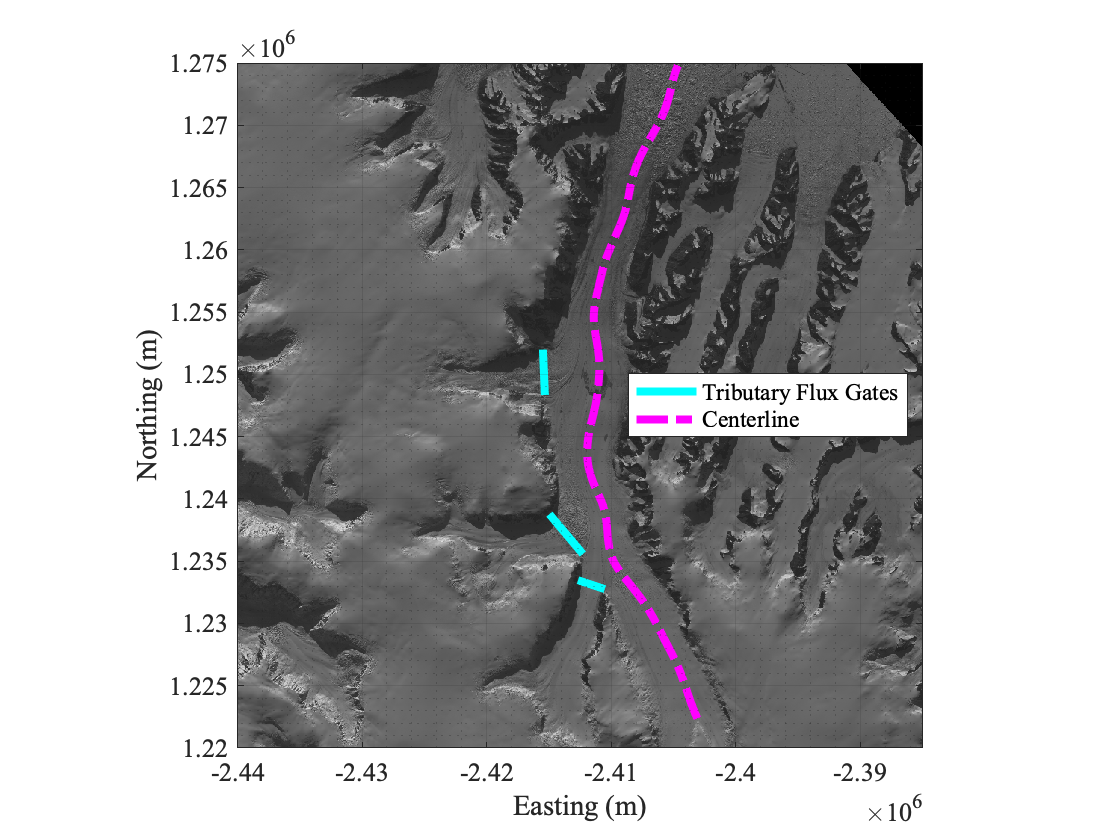

    landsat = dir('*B8.TIF');
    [LS,R] = geotiffread(landsat.name);
    [ny,nx] = size(LS);
    
    % Polar stereographic coordinates of image boundaries (from image metadata)
    x = linspace(min(R.XWorldLimits),max(R.XWorldLimits),nx);
    y = linspace(min(R.YWorldLimits),max(R.YWorldLimits),ny);
    figure; imagesc(x,y,flipud(LS)); colormap("gray");
    set(gca, 'YDir','normal','FontSize',13,'FontName','Times New Roman');
    xlabel('Easting (m)'); ylabel('Northing (m)');
    grid on; grid minor; axis equal; hold on;
    
    % Zoom to Crane 
    xlim([-2.44e6 -2.385e6]); ylim([1.220e6 1.275e6]); 
    
    % Load Crane Centerline, Tributary centerline and flux gates, and plot onto image 
    cd /Users/raineyaberle/Desktop/Research/CraneGlacier_modeling/inputs-outputs/
    load('Crane_TributaryA.mat');
    xb_w = load('Crane_TributaryB.mat').x; yb_w = load('Crane_TributaryB.mat').y;
    xc_w = load('Crane_TributaryC.mat').x; yc_w = load('Crane_TributaryC.mat').y;
    
    %plot(xa_cl,ya_cl,'-m','LineWidth',3,'DisplayName','TribA Centerline'); 
    p1 = plot(xa_w,ya_w,'-c','LineWidth',4);
    plot(xb_w,yb_w,'-c','LineWidth',4); 
    plot(xc_w,yc_w,'-c','LineWidth',4);

    cd ..
    x_cl = load('Crane_centerline.mat').x; y_cl = load('Crane_centerline.mat').y;

    % End centerline at 2011 Crane terminus position
    term = 138;
    %x_cl=x_cl(1:term); y_cl=y_cl(1:term);
    p2 = plot(x_cl,y_cl,'-.m','LineWidth',4,'DisplayName','Crane Centerline');
    legend([p1 p2],'Tributary Flux Gates','Centerline','Location','east');  
    
    % Save figure
    cd ../figures
    saveas(gcf,'CraneCenterline_Tributaries.png');
    
    hold off;

**2. Load necessary variables: **

- 2011 TerraSAR-X velocity

- 2011 RACMO2.3 climate variables: surface mass balance (SMB), snowfall (sf), snowmelt (sm), and runoff (ro) 

- 2011 NASA Operation IceBridge (OIB) surface and bed elevations for Crane centerline and tributary flux gates

*Note: 2011 velocities are sparse along Crane Glacier centerline. However, the 2016 velocities show nearly equivalent spatial distibution and speeds, but with more continous data. Therefore the 2016 velocity map will be used. 

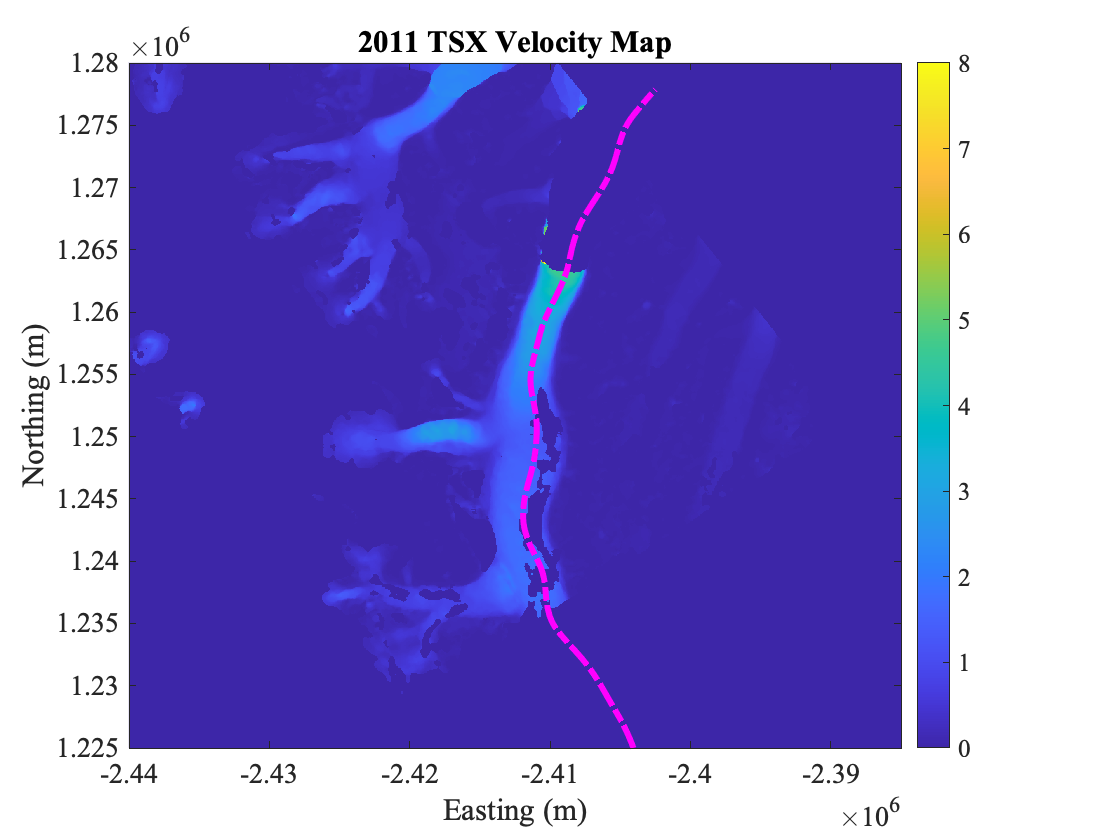

% 2011 TerraSAR-X velocity map
cd /Users/raineyaberle/Desktop/Research/Crane_modeling/velocities

    load('LarsenB_TSX_velocities.mat');
    u_x = {V(15).x}; u_x = u_x{:,:}; u_y = {V(15).y}; u_y = u_y{:,:};
    u = {V(15).speed}; u = u{:,:}; u_err = {V(15).speed_err}; u_err = u_err{:,:};
   
    %Interpolate speed along Crane centerline, tributary flux gates
    u_cl = 365.*interp2(u_x,u_y,u,x_cl,y_cl); % m/yr Crane centerline velocities
    ua_w = 365.*interp2(u_x,u_y,u,xa_w,ya_w); % m/yr TribA flux gate
    ub_w = 365.*interp2(u_x,u_y,u,xb_w,yb_w); % m/yr TribB flux gate 
    uc_w = 365.*interp2(u_x,u_y,u,xc_w,yc_w); % m/yr TribC flux gate
    
    %Define variables for distance along each profile (x,XA,XB,XC)
    x = []; x(1)=0;
    for i=2:length(x_cl)
        x(i)=sqrt((x_cl(i)-x_cl(i-1))^2+(y_cl(i)-y_cl(i-1))^2)+x(i-1);
    end
    XA_w = []; XA_w(1)=0;
    for i=2:length(xa_w)
        XA_w(i)=sqrt((xa_w(i)-xa_w(i-1))^2+(ya_w(i)-ya_w(i-1))^2)+XA_w(i-1);
    end
    XB_w = []; XB_w(1)=0;
    for i=2:length(xb_w)
        XB_w(i)=sqrt((xb_w(i)-xb_w(i-1))^2+(yb_w(i)-yb_w(i-1))^2)+XB_w(i-1);
    end   
    XC_w = []; XC_w(1)=0;
    for i=2:length(xc_w)
        XC_w(i)=sqrt((xc_w(i)-xc_w(i-1))^2+(yc_w(i)-yc_w(i-1))^2)+XC_w(i-1);
    end
        %Interpolate errors for each speed profile
        u_cl_err = 365.*interp2(u_x,u_y,u_err,x_cl,y_cl); % m/yr Crane centerline speed error
        ua_w_err = 365.*interp2(u_x,u_y,u_err,xa_w,ya_w); % m/yr TribA flux gate speed error
        ub_w_err = 365.*interp2(u_x,u_y,u_err,xb_w,yb_w); % m/yr TribB flux gate speed error 
        uc_w_err = 365.*interp2(u_x,u_y,u_err,xc_w,yc_w); % m/yr TribC flux gate speed error       
        %Matrices for error polygon fill
        u_cl_std = ([x fliplr(x); transpose(u_cl+u_cl_err) transpose(flipud(u_cl-u_cl_err))]);
        ua_w_std = ([XA_w fliplr(XA_w); ua_w+ua_w_err fliplr(ua_w-ua_w_err)]);
        ub_w_std = ([XB_w fliplr(XB_w); ub_w+ub_w_err fliplr(ub_w-ub_w_err)]);
        uc_w_std = ([XC_w fliplr(XC_w); uc_w+uc_w_err fliplr(uc_w-uc_w_err)]);
    
    %Plot resulting velocity profiles:
    %Regional Velocity Map
    imagesc(u_x,u_y,u); hold on; colormap('parula'); 
    colorbar; title('2011 TSX Velocity Map');
    set(gca,'YDir','normal','FontSize',14,'FontName','Times New Roman');
    plot(x_cl,y_cl,'-.m','LineWidth',3);
    xlim([-2.44e6 -2.385e6]); ylim([1.225e6 1.28e6]); caxis([0 8]); 
    xlabel('Easting (m)'); ylabel('Northing (m)'); hold off; 

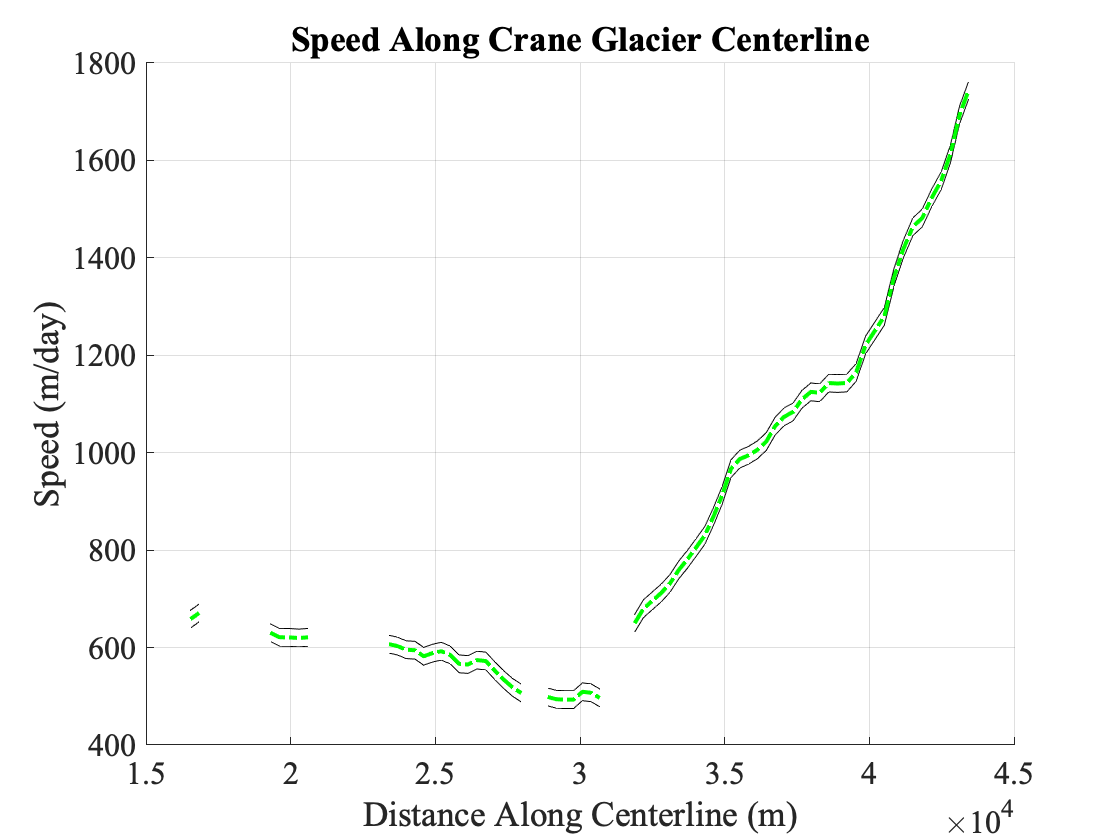

    
    %Crane Centerline
    figure; hold on; fill(u_cl_std(1,:),u_cl_std(2,:),[0.3010, 0.7450, 0.9330]);
    plot(x,u_cl,'-.g','LineWidth',2); grid on; 
    xlabel('Distance Along Centerline (m)'); ylabel('Speed (m/day)'); title('Speed Along Crane Glacier Centerline');
    set(gca,'FontSize',16,'FontName','Times New Roman');
    %ylim([0 1500]); 
    hold off;

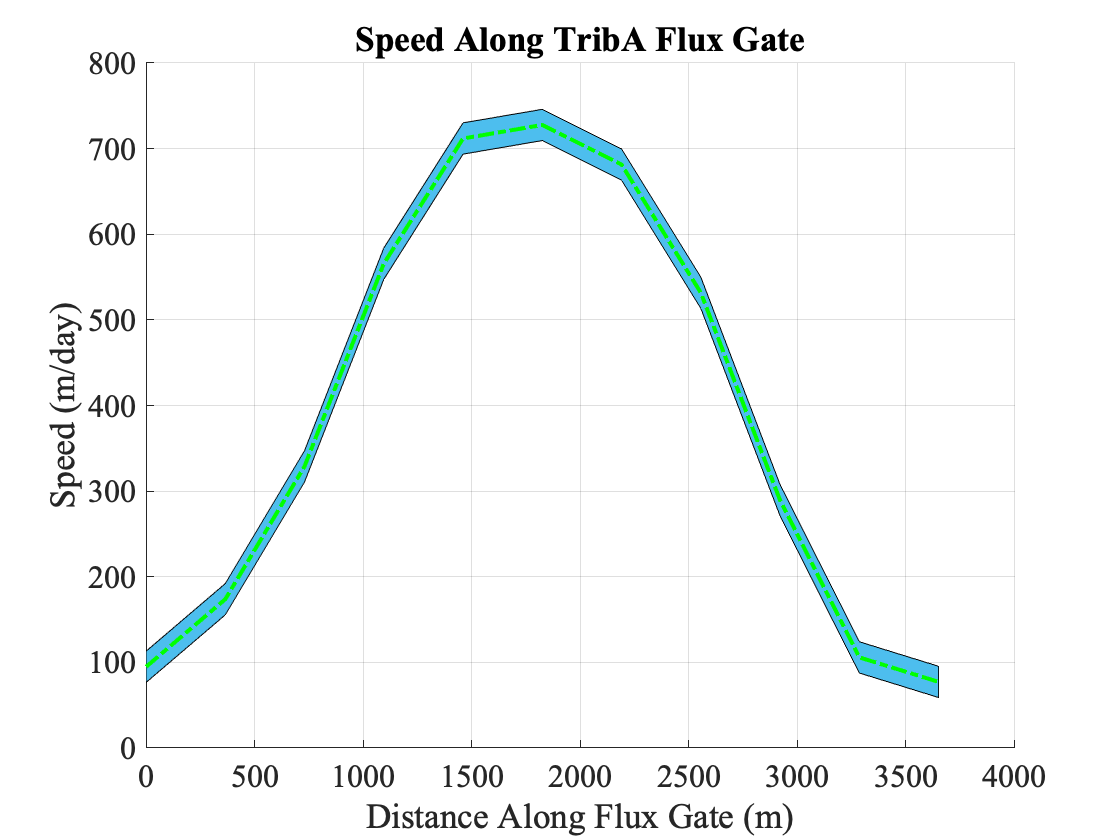

    
    %TribA Flux Gate
    figure; hold on; fill(ua_w_std(1,:),ua_w_std(2,:),[0.3010, 0.7450, 0.9330]);
    plot(XA_w,ua_w,'-.g','LineWidth',2); grid on;
    xlabel('Distance Along Flux Gate (m)'); ylabel('Speed (m/day)'); title('Speed Along TribA Flux Gate');
    set(gca,'FontSize',16,'FontName','Times New Roman');
    %ylim([0 900]);
    hold off;

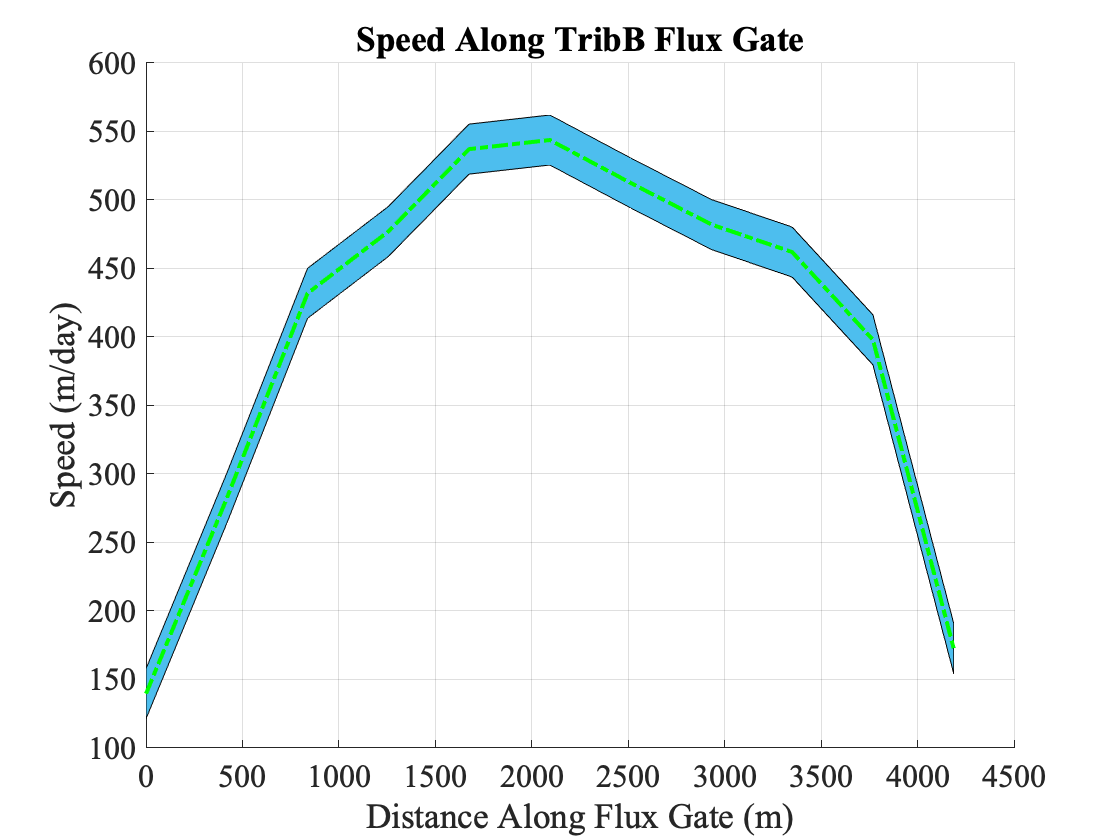

    
    %TribB Flux Gate
    figure; hold on; fill(ub_w_std(1,:),ub_w_std(2,:),[0.3010, 0.7450, 0.9330]);
    plot(XB_w,ub_w,'-.g','LineWidth',2); grid on;
    xlabel('Distance Along Flux Gate (m)'); ylabel('Speed (m/day)'); title('Speed Along TribB Flux Gate');
    set(gca,'FontSize',16,'FontName','Times New Roman');
    %ylim([0 900]);
    hold off;

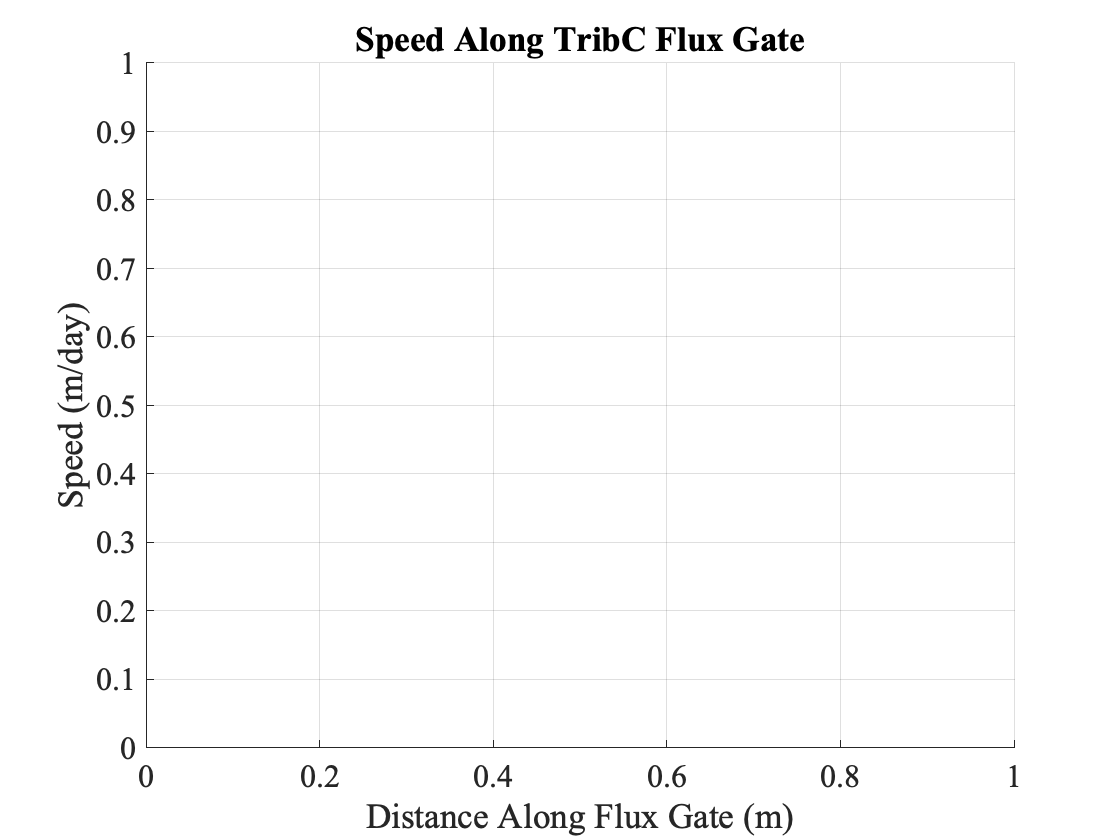

    
    %TribC Flux Gate
    figure; hold on; fill(uc_w_std(1,:),uc_w_std(2,:),[0.3010, 0.7450, 0.9330]);
    plot(XC_w,uc_w,'-.g','LineWidth',2); grid on;
    xlabel('Distance Along Flux Gate (m)'); ylabel('Speed (m/day)'); title('Speed Along TribC Flux Gate');
    set(gca,'FontSize',16,'FontName','Times New Roman');
    %ylim([0 900]);
    hold off;

% Mean 2011 RACMO2.3 climate variables    
    disp('Loading RACMO2.3 climate variables...');

Loading RACMO2.3 climate variables...


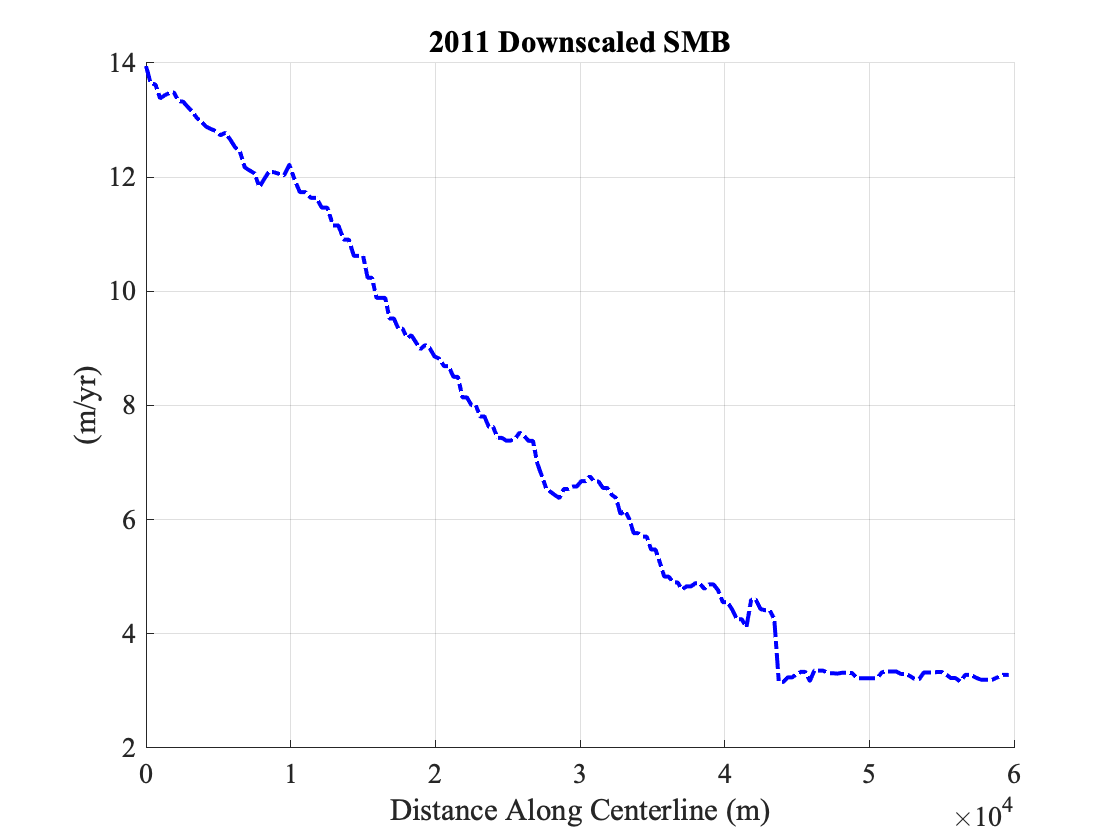


% Load Surface Mass Balance (smb), Snowfall (sf), Snowmelt (sm), Runoff (ro)
    cd /Users/raineyaberle/Desktop/Research/Crane_modeling/RACMO2.3
    smb_cl = load('Crane_downscaledSMB_2011.mat').smb_linear;
    %smb_cl = smb_cl(1:term);
    
    %Plot climate variables along Crane centerline
    figure; hold on; plot(x,smb_cl,'-.b','LineWidth',2,'DisplayName','SMB'); 
    xlabel('Distance along centerline (m)'); ylabel('SMB (m/yr)');
    grid on; title('2011 Downscaled SMB');
    set(gca,'FontSize',14,'FontName','Times New Roman');
    xlabel('Distance Along Centerline (m)'); ylabel('(m/yr)');
    
    hold off; 

    
% Calculate smb over each area increment (between each point along the centerline) 
% to calculate thickness added to Crane later    

    smb_Q=ones(1,term); % flux over each area along the centerline 
    for i=1:term
        smb_Q(i) = (smb_cl(i+1)+smb_cl(i))/2*(x(i+1)-x(i)); % m^2/yr
    end 
    

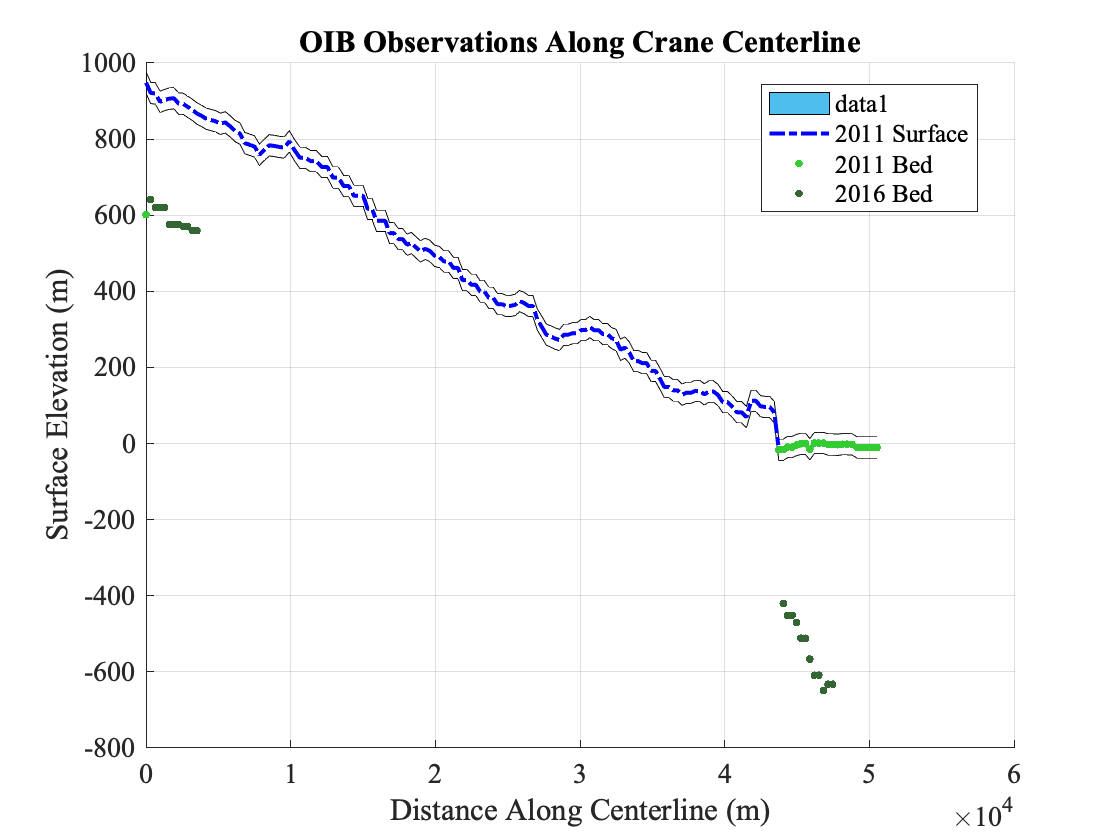

%NASA Operation IceBridge (OIB) surface and bed elevation data

%Note: Subtract the geoid height from OIB elevations, which are referenced
%to the ellipsoid
    %Convert centerline to lat lon
    cd /Users/raineyaberle/Desktop/Research/general_matlabcodes
    cl_latlon = ps2wgs(x_cl,y_cl,'StandardParallel',-71,'StandardMeridian',0);
    a_cl_latlon = ps2wgs(xa_cl,ya_cl,'StandardParallel',-71,'StandardMeridian',0);
    w_cl_latlon = ps2wgs(xa_w,ya_w,'StandardParallel',-71,'StandardMeridian',0);
    G = geoidheight(cl_latlon(:,1),cl_latlon(:,2));
    Ga_cl = transpose(geoidheight(a_cl_latlon(:,1),a_cl_latlon(:,2)));

% Load Crane centerline observations
    cd /Users/raineyaberle/Desktop/Research/Crane_modeling/BedandSurface
    Crane_OIB = load('Crane_OIBObservations_2009-2018.mat').Crane_OIB;
    % Load variables, resample along centerline, subtract geoid height
        hb_cl_2011 = Crane_OIB(3).bed - G;
        hb_cl_2016 = Crane_OIB(4).bed - G;       
        h_cl = Crane_OIB(3).surf - G;
        h_err = 28; %Surface obs. error = distance between two data points
    
    % Surface observations standard deviation
    h_cl_std = ([x fliplr(x); transpose(h_cl+h_err) transpose(flipud(h_cl-h_err))]);
    
    % Plot results
    figure; hold on; fill(h_cl_std(1,:),h_cl_std(2,:),[0.3010, 0.7450, 0.9330]);
    plot(x,h_cl,'-.b','LineWidth',2,'displayname','2011 Surface'); grid on;
    plot(x,hb_cl_2011,'.','color',[0.2,0.8,0.2],'displayname','2011 Bed','markersize',10);
    plot(x,hb_cl_2016,'.','color',[0.2,0.4,0.2],'displayname','2016 Bed','markersize',10);
    legend('Location','best');
    set(gca,'FontSize',14,'FontName','Times New Roman');
    xlabel('Distance Along Centerline (m)'); ylabel('Surface Elevation (m)');
    title('OIB Observations Along Crane Centerline');

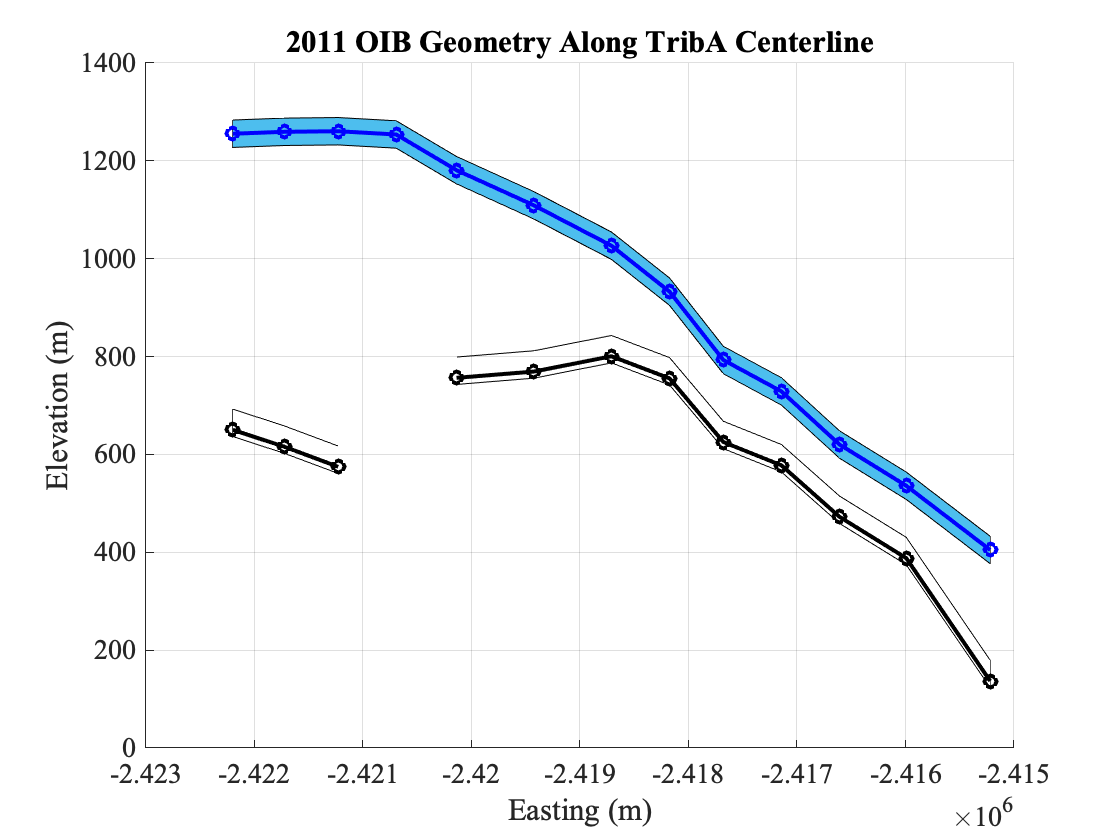

    
%Tributary A surface and bed
    load('Crane_TributaryA.mat','ha_cl','hba_cl');
    ha_cl = ha_cl-Ga_cl; 
    ha_cl_std = ([transpose(xa_cl) transpose(flipud(xa_cl)); ha_cl+h_err fliplr(ha_cl-h_err)]);    
    hba_cl_std = ([transpose(xa_cl) transpose(flipud(xa_cl)); hba_cl+h_err fliplr(hba_cl-h_err)]);
    hba_cl = hba_cl-Ga_cl;
    figure; hold on; set(gca,'FontSize',14,'FontName','Times New Roman');
    fill(ha_cl_std(1,:),ha_cl_std(2,:),[0.3010, 0.7450, 0.9330]);
    plot(xa_cl,ha_cl,'-ob','LineWidth',2,'DisplayName','Surface'); 
    fill(hba_cl_std(1,:),hba_cl_std(2,:),[0.3010, 0.7450, 0.9330]);
    plot(xa_cl,hba_cl,'-ok','LineWidth',2,'DisplayName','Bed');
    grid on; xlabel('Easting (m)'); ylabel('Elevation (m)');
    title('2011 OIB Geometry Along TribA Centerline');
    hold off;

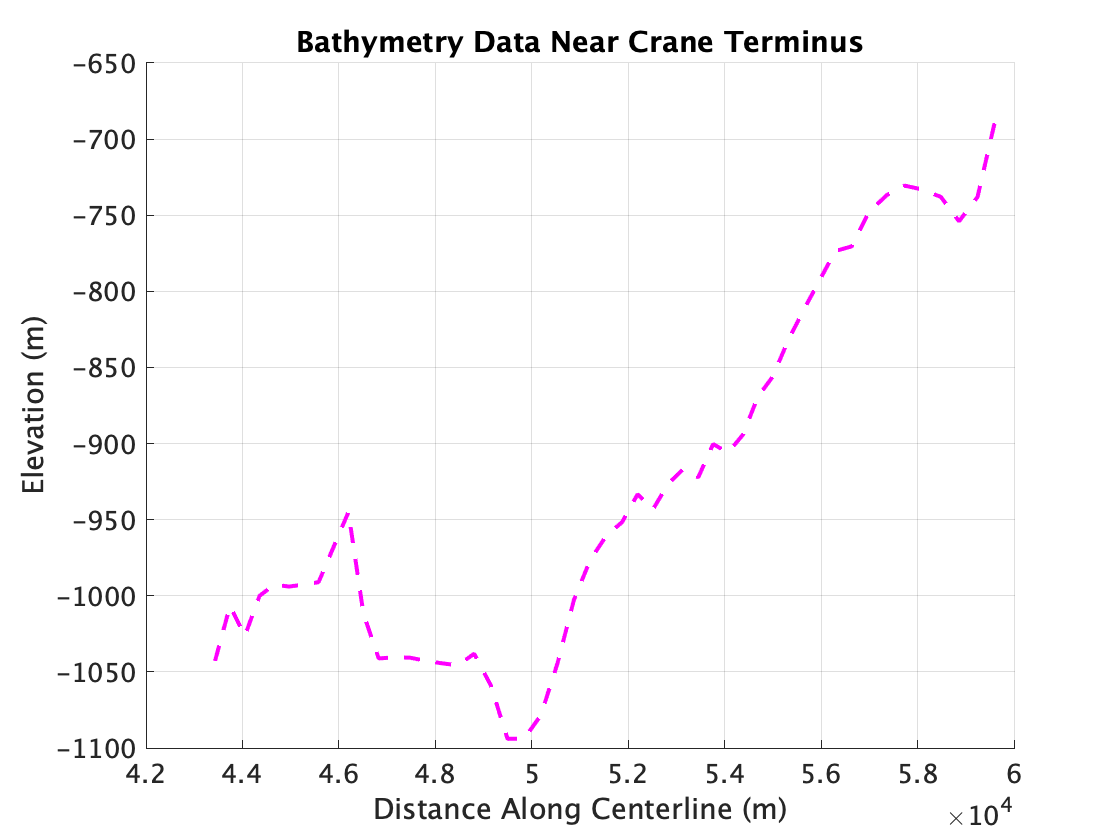

%Load bathymetry data
cd /Users/raineyaberle/Desktop/Research/Crane_modeling/BedandSurface/
cl_trough = load('Crane_BathymetryData.mat').cl_trough;
%Make values negative to reflect elevation below sea level instead of depth
cl_trough = -cl_trough; 

figure; hold on; 
set(gca,'FontSize',13,'FontName','Calibri');
plot(x,cl_trough,'--m','displayname','Trough','linewidth',2);
%legend('Location','northwest'); 
xlabel('Distance Along Centerline (m)'); ylabel('Elevation (m)');
title('Bathymetry Data Near Crane Terminus'); grid on;
hold off;

**3. Run trials of bed elevation calculation**

*        Floating ice tongue: *

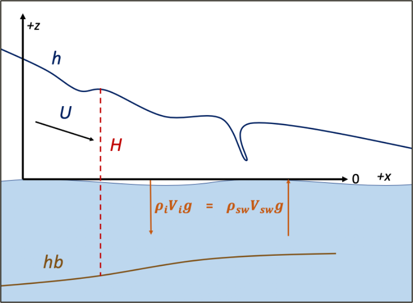

***ρ_i*V_i*g = ρ_sw*V_sw*g***

***H_i = (ρ_i/ρ_sw)*H_sw***

***hb = h - H_i = (ρ_i/(ρ_i-ρ_sw))*h ***

***hb ~ -917/111*h***

*        Grounded glacier bed:*

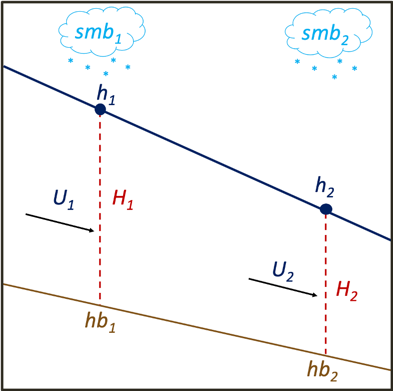

***Qin = Qout***

***H1 = (U2H2 – smb1) / U1***

***hb1 = h1 - H1***

***H2 = (U2H2+smb1) / U2***

***Trial #1:*** *Mass conservation ****WITHOUT**** Crane tributary ice volume fluxes included*

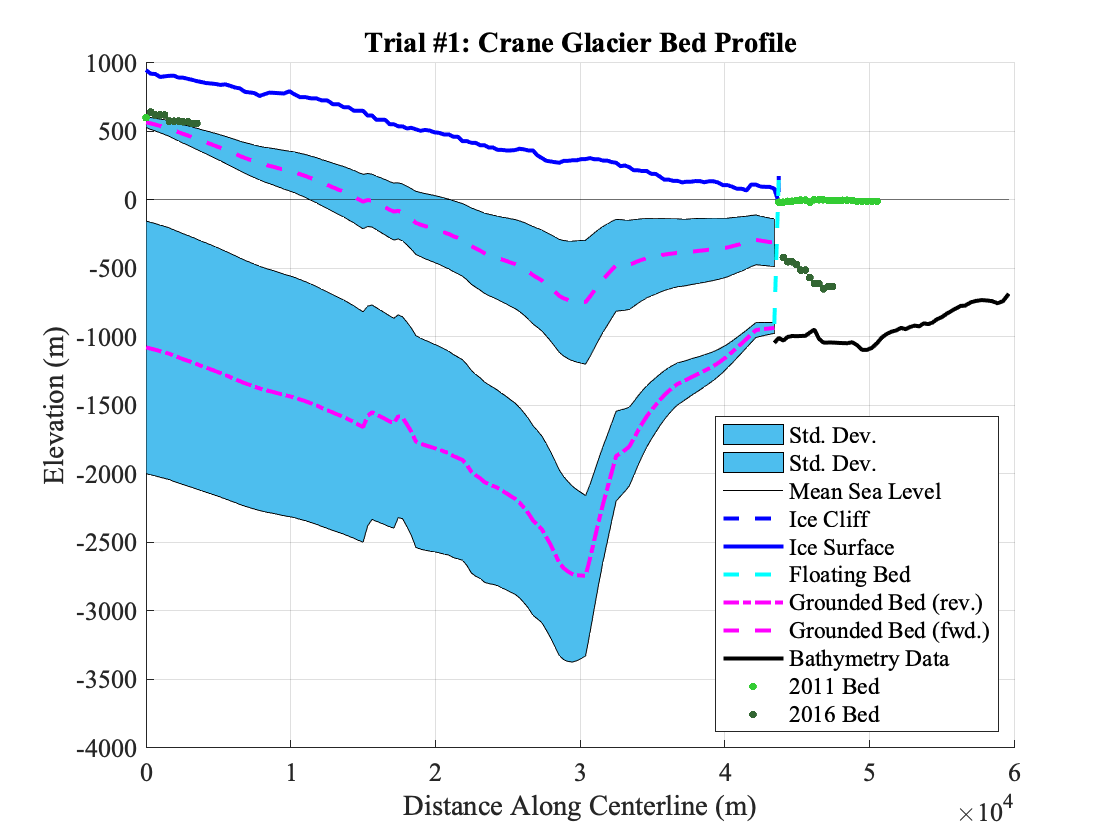

%Use a moving mean of surface and velocity
h_m = movmean(h_cl,10,'omitnan');
u_m = movmean(u_cl,10,'omitnan'); u_m(isnan(u_m)) =u_m(find(~isnan(u_m),1));

%Establish floating ice tongue range
fl_start = 137; %Starting index of floating ice tongue 
fl_end = term; %Ending index of floating ice tongue
    
hb_fl = []; %bed of floating ice tongue 
hb_gr_rev = []; %bed of grounded glacier (reverse calculation)
hb_gr_fwd = []; %bed of grounded glacier (forward calculation)
H1 = []; %thickness of grounded glacier (calculated iteratively starting at TERMINUS)
H2 = []; %thickness of grounded glacier (calculated interatively starting at TOP of centerline)
H_fl = []; %thickness of floating glacier
H1_err = []; H2_err=[]; hb_fl_std = []; hb_gr_std_fwd = []; hb_gr_std_rev = [];

rho_i = 917; %Ice density (kg/m^3)
rho_sw = 1000; %Seawater density (kg/m^3)

%Use buoyancy force balance to calculate bed 
% from terminus to approximate grounding line
    for i=fl_end:-1:fl_start
        hb_fl(i) = h_cl(i)*(rho_i/(rho_i-rho_sw));
        H_fl(i) = h_cl(i)-hb_fl(i);
    end 
    hb_fl(hb_fl==0) = NaN; hb_fl = transpose(hb_fl); H_fl(H_fl==0)=NaN;
    
%Use conservation of mass to calculate thickness on land
    %Reverse direction
    H1(fl_start) = H_fl(fl_start);
    for i=(fl_start-1):-1:1
        H1(i) = (u_m(i+1)*H1(i+1)-smb_Q(i))/u_m(i); % m 
    end
    
    %Forward direction
    H2(1,1) = 350; %initial thickness
    for i=2:fl_start
        H2(i) = (u_m(i-1)*H2(i-1)+smb_Q(i))/u_m(i);
    end

    %Substract thickness from surface to get bed elevation, add to the 
    %bed elevation variable
    hb_gr_rev = h_m(1:(fl_start))-transpose(H1);
    hb_gr_fwd = h_m(1:(fl_start))-transpose(H2);
    
%Calculate standard deviation
    %(u*H-smb*x)/u
    %Floating
    hb_fl_std = ([x(end) x(end); hb_fl(end)+h_err hb_fl(end)-h_err]);
    %Reverse
    for i=length(H1):-1:1
        if i==length(hb_gr_rev)
            H1_err(i) = sqrt(2)*h_err;
        else 
            H1_err(i)=abs(H1(i))*sqrt((u_cl_err(i+1)/u_m(i+1))^2+(H1_err(i+1)/H1(i+1))^2+(u_cl_err(i)/u_m(i))^2);
        end 
    end 
    %Forward
    for i=1:length(H2)
        if i==1
            H2_err(i) = sqrt(2)*h_err;
        else
            H2_err(i) = abs(H2(i))*sqrt((u_cl_err(i-1)/u_m(i-1))^2+(H2_err(i-1)/H2(i-1))^2+(u_cl_err(i)/u_m(i))^2);
        end 
    end 
    
    hb_gr_std_rev = ([x(1:fl_start) fliplr(x(1:fl_start)); transpose(h_m(1:fl_start))-(H1-H1_err) fliplr(transpose(h_m(1:fl_start))-(H1+H1_err))]); 
    hb_gr_std_fwd = ([x(1:fl_start) fliplr(x(1:fl_start)); transpose(h_m(1:fl_start))-(H2-H2_err) fliplr(transpose(h_m(1:fl_start))-(H2+H2_err))]); 
    
%Vectors for mean sea level and ice cliff at terminus
    msl = ([x; zeros(length(x))]);
    icecliff = ([x(fl_end) hb_fl(fl_end); x(fl_end) 0]);

%Plot resulting bed elevations
    figure; hold on;
    fill(hb_gr_std_rev(1,:),hb_gr_std_rev(2,:),[0.3010, 0.7450, 0.9330],'DisplayName','Std. Dev.');
    fill(hb_gr_std_fwd(1,:),hb_gr_std_fwd(2,:),[0.3010, 0.7450, 0.9330],'DisplayName','Std. Dev.');    
    plot(msl(1,:),msl(2,:),'-k','LineWidth',0.5,'DisplayName','Mean Sea Level'); 
    plot(icecliff(:,1),icecliff(:,2),'--b','LineWidth',2,'DisplayName','Ice Cliff');    
    plot(x,h_cl,'-b','LineWidth',2,'DisplayName','Ice Surface'); 
    ylim([-4000 1000]);
    plot(x(1:fl_end),hb_fl,'--c','linewidth',2,'DisplayName','Floating Bed');    
    plot(x(1:fl_start),hb_gr_rev,'-.m','LineWidth',2,'DisplayName','Grounded Bed (rev.)');
    plot(x(1:fl_start),hb_gr_fwd,'--m','LineWidth',2,'DisplayName','Grounded Bed (fwd.)');    
    plot(x,cl_trough,'-k','linewidth',2,'displayname','Bathymetry Data');
    plot(x,hb_cl_2011,'.','color',[0.2,0.8,0.2],'displayname','2011 Bed','markersize',10);
    plot(x,hb_cl_2016,'.','color',[0.2,0.4,0.2],'displayname','2016 Bed','markersize',10);    
    grid on; set(gca,'FontSize',13,'FontName','Times New Roman');
    legend('Location','southeast'); 
    title('Trial #1: Crane Glacier Bed Profile');xlabel('Distance Along Centerline (m)'); ylabel('Elevation (m)');
    hold off;

***Trial #2: ****Mass conservation ****WITH ****Crane tributary ice volume fluxes included, calculate in both the forward and reverse direction*

hb_fl = []; % bed of floating ice tongue 
hb_gr_rev = []; % bed of grounded glacier (reverse calculation)
hb_gr_fwd = []; % bed of grounded glacier (forward calculation)
H1 = []; % thickness of grounded glacier (calculated iteratively starting at TERMINUS)
H2 = []; % thickness of grounded glacier (calculated interatively starting at TOP of centerline)
H_fl = []; %thickness of floating glacier
        
%Calculate ice volume flux from Crane Tributaries:
    % Point along centerline at which tributaries add to Crane width
    fga_pt = 87; fgb_pt = 47; fgc_pt = 37;

%Tributary A (bed elevation and velocities at flux gate available)
    %Calculate cross-sectional area assuming half-ellipsoid geometry
    H_a = ha_cl(end)-hba_cl(end); % TribA centerline thickness
    W_a = sqrt((xa_w(end)-xa_w(1))^2+(ya_w(end)-ya_w(1))^2);% TribA flux gate width
    A_a = pi*H_a*W_a/2;

    %Calculate mean velocity along flux gate
    u_a = mean(ua_w);
    
    %Calculate total ice volume flux across flux gate
    V_a = u_a*A_a; % m^3/yr
        
    % Load glacier width
    cd /Users/raineyaberle/Desktop/Research/Crane_modeling
    W = load('Crane_centerline_W.mat').W;

    % Divide the total volume by the average width and by the total number
    % of points between the flux gate and the terminus
    %       V = H*W*L --> Q = H*L = V/W
    tribA_Q = V_a/(nanmean(W(fga_pt:term))*(term-fga_pt)); % m^2/yr
 

**Note:** Crane Tributaries B & C do not have bed elevation data. Therefore, assume a constant width:thickness ratio and use the width:thickness ratio of TribA to calculate the area of TribB & TribC. 

W_a / H_a = W_b / H_b = W_c / H_c

H_b = H_a * W_b / W_a

H_c = H_a * W_c / W_a

%Tributaries B & C
%Calculate cross-sectional area assuming half-ellipsoid geometry
    W_b = sqrt((xb_w(end)-xb_w(1))^2+(yb_w(end)-yb_w(1))^2);% (m) TribB flux gate width
    W_c = sqrt((xc_w(end)-xc_w(1))^2+(yc_w(end)-yc_w(1))^2);% (m) TribC flux gate width
    H_b = H_a*W_b/W_a; H_c = H_a*W_c/W_a; % (m) TribB & TribC flux gate thicknesses
    A_b = pi*H_b*W_b/2; A_c = pi*H_c*W_c/2; % (m^2) TribB & TribC flux gate areas

    %Calculate mean velocity along flux gates (no TribC velocity data - use
    %mean TribB velocity)
    u_b = mean(ua_w); u_c = u_b; % m yr^-1
    
    %Calculate total ice volume flux across flux gate
    V_b = u_b*A_b; V_c = u_c*A_c; %m^3/yr
        
    %Divide volume by the average Crane width and length from flux gate to terminus
    % to calculate avg annual thickness contribution   
        %   V = Q*L --> W = V/L (where Q = flux across a control area)
        tribB_Q = V_b/(nanmean(W(fgb_pt:term))*(term-fgb_pt)); % m^2/yr
        tribC_Q = V_c/(nanmean(W(fgc_pt:term))*(term-fgc_pt)); % m^2/yr
    
%Use buoyancy force balance to calculate bed 
% from terminus to approximate grounding line
    for i=fl_end:-1:fl_start
        hb_fl(i) = h_m(i)*(rho_i/(rho_i-rho_sw));
        H_fl(i) = h_m(i)-hb_fl(i);
    end 
    hb_fl(hb_fl==0) = NaN; hb_fl = transpose(hb_fl); H_fl(H_fl==0)=NaN;
    
%Use conservation of mass to calculate thickness on land
    %Reverse direction
    H1(fl_start,1)=h_m(fl_start)-hb_fl(fl_start);
    
    for i=(fl_start-1):-1:fga_pt
        H1(i) = (u_m(i+1)*H1(i+1)-smb_Q(i)-tribA_Q-tribB_Q-tribC_Q)/u_m(i);
    end 
    for i=(fga_pt-1):-1:fgb_pt
        H1(i) = (u_m(i+1)*H1(i+1)-smb_Q(i)-tribB_Q-tribC_Q)/u_m(i);
    end 
    for i=(fgb_pt-1):-1:fgc_pt
        H1(i) = (u_m(i+1)*H1(i+1)-smb_Q(i)-tribC_Q)/u_m(i);        
    end 
    for i=(fgc_pt-1):-1:1
        H1(i) = (u_m(i+1)*H1(i+1)-smb_Q(i))/u_m(i);                
    end 
    
    %Forward direction
    H2(1,1) = 345; %initial thickness
    for i=2:fgc_pt
        H2(i) = (u_m(i-1)*H2(i-1)+smb_Q(i))/u_m(i);
    end
    for i=(fgc_pt+1):fgb_pt
        H2(i) = (u_m(i-1)*H2(i-1)+smb_Q(i)+tribC_Q)/u_m(i);
    end
    for i=(fgb_pt+1):fga_pt
        H2(i) = (u_m(i-1)*H2(i-1)+smb_Q(i)+tribC_Q+tribB_Q)/u_m(i);
    end    
    for i=(fga_pt+1):fl_end
        H2(i) = (u_m(i-1)*H2(i-1)+smb_Q(i)+tribC_Q+tribB_Q+tribA_Q)/u_m(i);
    end 
    
    %Substract thickness from surface to get bed elevation, add to the 
    %bed elevation variable
    hb_gr_rev = h_m(1:fl_start)-H1;
    hb_gr_fwd = h_m(1:fl_end)-transpose(H2);
    
%Calculate standard deviation
    %(u*H-smb*x)/u
    %Floating
    hb_fl_std = ([x(fl_start:fl_end) fliplr(x(fl_start:fl_end)); transpose(hb_fl(fl_start:fl_end)+h_err) fliplr(transpose(hb_fl(fl_start:fl_end)-h_err))]);
    %Reverse
    for i=length(H1):-1:1
        if i==length(hb_gr_rev)
            H1_err(i) = sqrt(2)*h_err;
        else 
            H1_err(i)=abs(H1(i))*sqrt((u_cl_err(i+1)/u_m(i+1))^2+(H1_err(i+1)/H1(i+1))^2+(u_cl_err(i)/u_m(i))^2);
        end 
    end 
    %Forward
    for i=1:length(H2)
        if i==1
            H2_err(i) = sqrt(2)*h_err;
        else
            H2_err(i) = abs(H2(i))*sqrt((u_cl_err(i-1)/u_m(i-1))^2+(H2_err(i-1)/H2(i-1))^2+(u_cl_err(i)/u_m(i))^2);
        end 
    end 
    
    hb_gr_std_rev = ([x(1:fl_start) fliplr(x(1:fl_start)); transpose(h_m(1:fl_start)-(H1-transpose(H1_err))) fliplr(transpose(h_m(1:fl_start)-(H1+transpose(H1_err))))]); 
    hb_gr_std_fwd = ([x(1:fl_end) fliplr(x(1:fl_end)); transpose(h_m(1:fl_end))-(H2-H2_err) fliplr(transpose(h_m(1:fl_end))-(H2+H2_err))]); 
    
% Vectors for mean sea level and ice cliff at terminus
    msl = ([x; zeros(length(x))]);
    icecliff = ([x(fl_end) hb_fl(end); x(fl_end) 0]);

% Plot resulting bed elevations
    figure; hold on;
    fill(hb_gr_std_fwd(1,:),hb_gr_std_fwd(2,:),[0.3010, 0.7450, 0.9330],'DisplayName','Std. Dev.');    
    %fill(hb_gr_std_rev(1,:),hb_gr_std_rev(2,:),[0.3010, 0.7450, 0.9330],'HandleVisibility','off');
    plot(msl(1,:),msl(2,:),'-k','LineWidth',0.5,'HandleVisibility','off'); 
    plot(icecliff(:,1),icecliff(:,2),'--b','LineWidth',2,'HandleVisibility','off');    
    plot(x,h_cl,'-b','LineWidth',2,'DisplayName','2011 OIB Ice Surface'); 
    ylim([-3000 1000]); xlim([0 6e4]);
    %plot(x(1:fl_end),hb_fl,'-c','linewidth',2,'DisplayName','Floating Bed');    
    %plot(x(1:fl_start),hb_gr_rev,'-.m','LineWidth',2,'DisplayName','Grounded Bed (rev)');
    plot(x(1:fl_end),hb_gr_fwd,'--m','LineWidth',2,'DisplayName','Calculated Bed');    
    plot(x,cl_trough,'-k','linewidth',2,'displayname','2006 Bathymetry');
    plot(x,hb_cl_2011,'.','color',[0.2,0.8,0.2],'displayname','2011 OIB Bed','markersize',10);
    plot(x,hb_cl_2016,'.','color',[0.2,0.4,0.2],'displayname','2016 OIB Bed','markersize',10);
    grid on; set(gca,'FontSize',14,'FontName','Arial');
    legend('Location','southeast'); 
    title('Crane Glacier Calculated Bed Profile'); xlabel('Distance Along Centerline (m)'); ylabel('Elevation (m)');
    
    % Save figure as image
   cd /Users/raineyaberle/Desktop/Research/figures
   saveas(gcf,'Crane_CalculatedBed.png');
   disp('Figure saved as .png');

Figure saved as .png


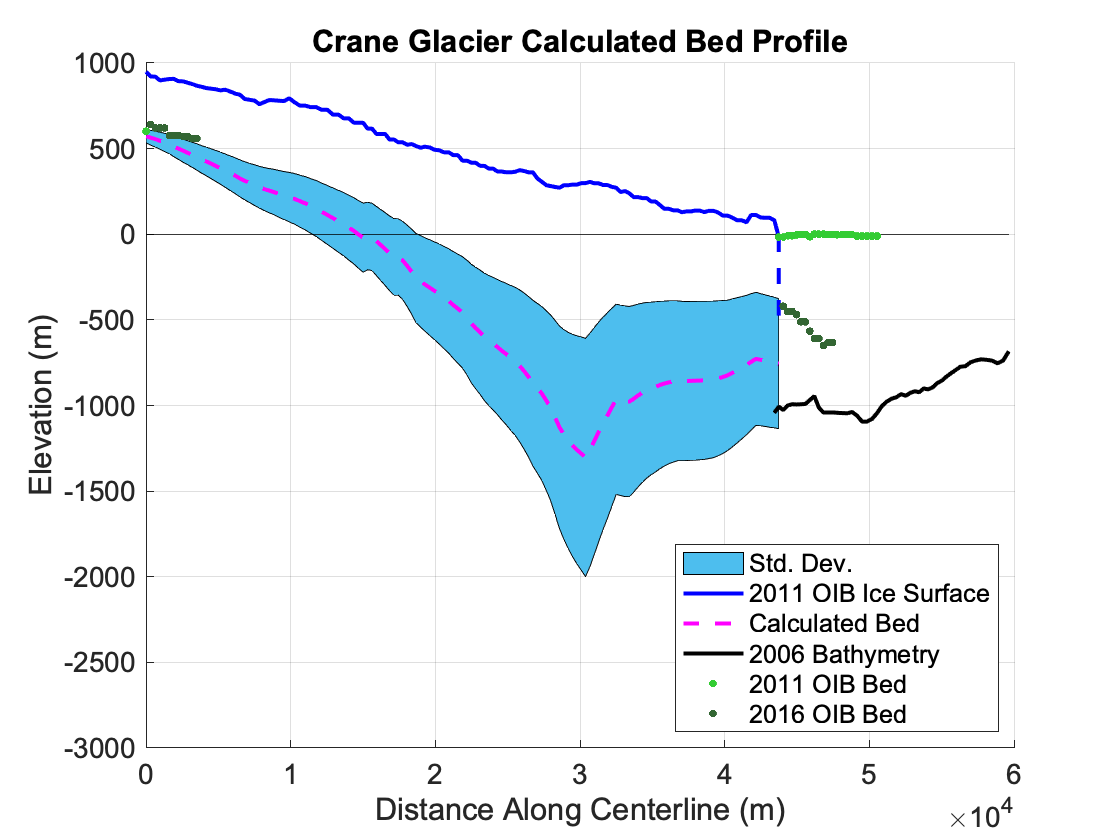

   hold off;

***Trial #3: ****Testing sensitivity to ice density (rho_i) using Trial #2 conditions*

Vary ice density by 10% from ice divide to terminus

    At ice divide: rho_i = 917 x 0.9 (kg / m^3)

    At terminus: rho_i = 917 x 1.1 (kg / m^3)

Because the density is no longer constant here, we must use conservation of mass (not volume):

Q_in = Q_out

(rho1*H1*W1*U1)+ smb1= rho2*H2*W2*U2

H1 = [ (rho2*H2*W2*U2) - smb1 ] / (rho1*W1*U1)    [reverse]

H2 = [ (rho1*H1*W1*U1) + smb1 ] / (rho2*W2*U2)     [forward]

Note: Must convert smb values from m/yr to kg/yr to balance equation

smb (m/yr) * W1 (m) * H1 (m) * rho( kg/m^3) = smb (kg/yr)

hb_fl = []; % bed of floating ice tongue 
hb_gr_rev = []; % bed of grounded glacier (reverse calculation)
hb_gr_fwd = []; % bed of grounded glacier (forward calculation)
H1 = []; % thickness of grounded glacier (calculated iteratively starting at TERMINUS)
H2 = []; % thickness of grounded glacier (calculated interatively starting at TOP of centerline)
H_fl = []; % thickness of floating glacier

W_m = movmean(W,20); % Moving mean of glacier width

% Vary ice density along centerline - least dense at ice divide, 
% more dense at terminus

rho_i = []; % density of ice (kg/m^3)
inc = abs(917*0.99-917*1.01)/(length(x)-1);
for i=1:length(x)
    if i==1
        rho_i(i)= 917*0.9;        
    else 
        rho_i(i)= inc+rho_i(i-1);
    end 
end 

% Use buoyancy force balance to calculate bed 
% from terminus to approximate grounding line
    for i=fl_end:-1:fl_start
        hb_fl(i) = h_m(i)*(917/(917-rho_sw));
        H_fl(i) = h_m(i)-hb_fl(i);
    end 
    hb_fl(hb_fl==0) = NaN; hb_fl = transpose(hb_fl); H_fl(H_fl==0)=NaN;
    
% Use conservation of mass to calculate thickness on land
    % Reverse direction
    H1(fl_start,1)=h_m(fl_start)-hb_fl(fl_start);
    
    for i=(fl_start-1):-1:fga_pt
        H1(i) = (u_m(i+1)*H1(i+1)*rho_i(i+1)-(smb_Q(i)+tribA_Q+tribB_Q+tribC_Q)*(rho_i(i)))/(u_m(i)*rho_i(i));
    end 
    for i=(fga_pt-1):-1:fgb_pt
        H1(i) = (u_m(i+1)*H1(i+1)*rho_i(i+1)-(smb_Q(i)+tribB_Q+tribC_Q)*(rho_i(i)))/(u_m(i)*rho_i(i));
    end 
    for i=(fgb_pt-1):-1:fgc_pt
        H1(i) = (u_m(i+1)*H1(i+1)*rho_i(i+1)-(smb_Q(i)+tribC_Q)*(rho_i(i)))/(u_m(i)*rho_i(i));
    end 
    for i=(fgc_pt-1):-1:1
        H1(i) = (u_m(i+1)*H1(i+1)*rho_i(i+1)-(smb_Q(i)*rho_i(i)))/(u_m(i)*rho_i(i));
    end 
    
    % Forward direction
    H2(1) = h_cl(1)-hb_cl_2011(1); % initial thickness from OIB observations
    %H2(2:12) = h_cl(2:12)-hb_cl_2016(2:12);
    for i=2:fgc_pt
        H2(i) = ((u_m(i-1)*H1(i-1)+smb_Q(i-1))*rho_i(i-1))/(u_m(i)*rho_i(i));
    end
    for i=(fgc_pt+1):fgb_pt
        H2(i) = ((u_m(i-1)*H1(i-1)+smb_Q(i-1)+tribC_Q)*rho_i(i-1))/(u_m(i)*rho_i(i));
    end
    for i=(fgb_pt+1):fga_pt
        H2(i) = ((u_m(i-1)*H1(i-1)+smb_Q(i-1)+tribC_Q+tribB_Q)*rho_i(i-1))/(u_m(i)*rho_i(i));
    end    
    for i=(fga_pt+1):fl_start
        H2(i) = ((u_m(i-1)*H1(i-1)+smb_Q(i-1)+tribC_Q+tribB_Q+tribA_Q)*rho_i(i-1))/(u_m(i)*rho_i(i));
    end 
    
    % Substract thickness from surface to get bed elevation, add to the 
    % bed elevation variable
    hb_gr_rev = h_m(1:fl_start)-H1;
    hb_gr_fwd = h_m(1:fl_start)-transpose(H2);
    
% Calculate standard deviation
    % (u*H-smb*x)/u
    % Floating
    hb_fl_std = ([x(fl_start:fl_end) fliplr(x(fl_start:fl_end)); transpose(hb_fl(fl_start:fl_end)+h_err) fliplr(transpose(hb_fl(fl_start:fl_end)-h_err))]);
    % Reverse
    for i=length(H1):-1:1
        if i==length(hb_gr_rev)
            H1_err(i) = sqrt(2)*h_err;
        else 
            H1_err(i)=abs(H1(i))*sqrt((u_cl_err(i+1)/u_m(i+1))^2+(H1_err(i+1)/H1(i+1))^2+(u_cl_err(i)/u_m(i))^2);
        end 
    end 
    % Forward
    for i=1:length(H2)
        if i==1
            H2_err(i) = sqrt(2)*h_err;
        else
            H2_err(i) = abs(H2(i))*sqrt((u_cl_err(i-1)/u_m(i-1))^2+(H2_err(i-1)/H2(i-1))^2+(u_cl_err(i)/u_m(i))^2);
        end 
    end 
    
    hb_gr_std_rev = ([x(1:fl_start) fliplr(x(1:fl_start)); transpose(h_m(1:fl_start)-(H1-transpose(H1_err))) fliplr(transpose(h_m(1:fl_start)-(H1+transpose(H1_err))))]); 
    hb_gr_std_fwd = ([x(1:fl_start) fliplr(x(1:fl_start)); transpose(h_m(1:fl_start))-(H2-H2_err) fliplr(transpose(h_m(1:fl_start))-(H2+H2_err))]); 
    
% Vectors for mean sea level and ice cliff at terminus
    msl = ([x; zeros(length(x))]);
    icecliff = ([x(fl_end) hb_fl(end); x(fl_end) 0]);

% Plot resulting bed elevations
    figure; hold on;
    fill(hb_gr_std_fwd(1,:),hb_gr_std_fwd(2,:),[0.3010, 0.7450, 0.9330],'DisplayName','Std. Dev.');    
    fill(hb_gr_std_rev(1,:),hb_gr_std_rev(2,:),[0.3010, 0.7450, 0.9330],'HandleVisibility','off');
    plot(msl(1,:),msl(2,:),'-k','LineWidth',0.5,'HandleVisibility','off'); 
    plot(icecliff(:,1),icecliff(:,2),'--b','LineWidth',2,'HandleVisibility','off');    
    plot(x,h_cl,'-b','LineWidth',2,'DisplayName','Ice Surface'); 
    ylim([-2000 1000]); xlim([0 6e4]);
    plot(x(1:fl_end),hb_fl,'-c','linewidth',2,'DisplayName','Floating Bed');    
    plot(x(1:fl_start),hb_gr_rev,'-.m','LineWidth',2,'DisplayName','Grounded Bed (rev)');
    plot(x(1:fl_start),hb_gr_fwd,'--m','LineWidth',2,'DisplayName','Grounded Bed (fwd)');    
    plot(x,cl_trough,'-k','linewidth',2,'displayname','Bathymetry Data');
    plot(x,hb_cl_2011,'.','color',[0.2,0.8,0.2],'displayname','2011 Bed','markersize',10);
    plot(x,hb_cl_2016,'.','color',[0.2,0.4,0.2],'displayname','2016 Bed','markersize',10);
    grid on; set(gca,'FontSize',14,'FontName','Times New Roman');
    legend('Location','southwest'); 
    title('Trial #3: Crane Glacier Bed Profile');
    xlabel('Distance Along Centerline (m)'); ylabel('Elevation (m)');
    
% Save 
    cd /Users/raineyaberle/Desktop/Research/figures
    saveas(gcf,'Crane_CalculatedBed_Trial#3_MassConservation.png');
    disp('Figure saved as .png');

Figure saved as .png


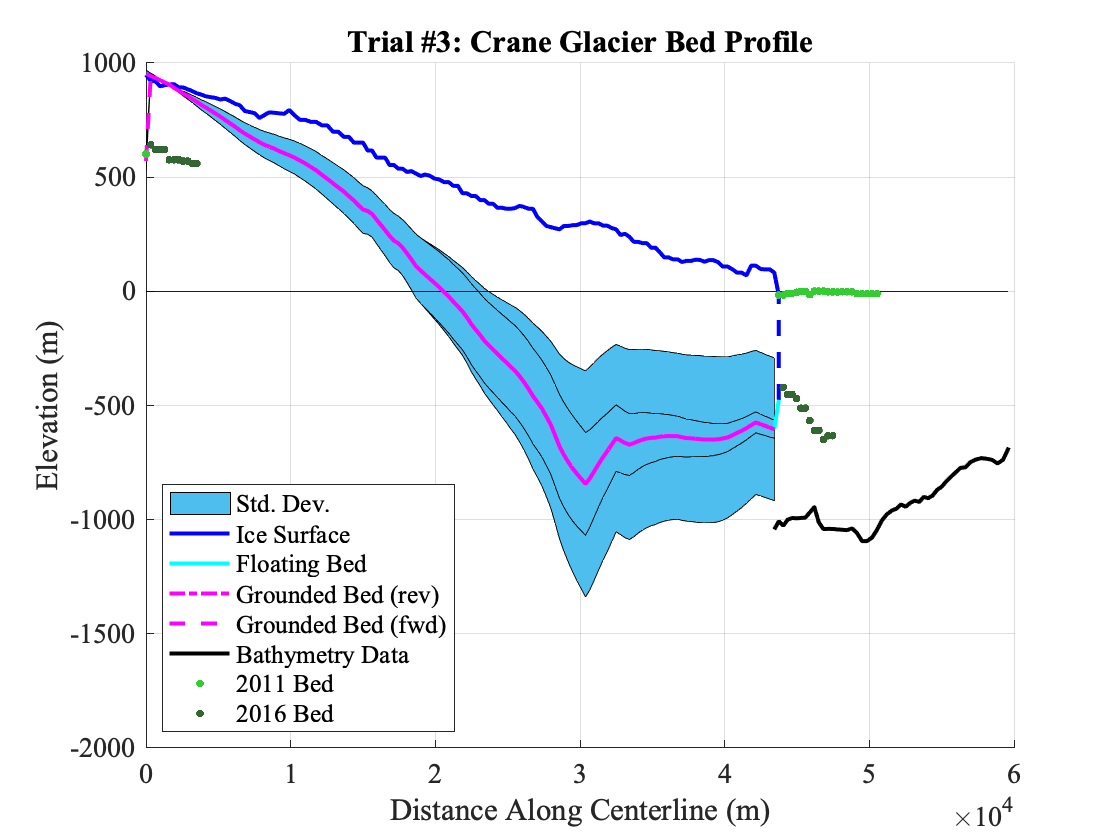

    
    hold off;

### Save a Crane bed profile for flowline model initialization

Use the above buoyancy calculations, bathymetry observations, and OIB bed observations near the ice divide as constraints to save a reasonable bed profile within the uncertainty of results for Crane Glacier. 

hb = ones(1,term);
hb(1) = hb_gr_fwd(1); % Use first value in forward calculation (OIB observations)

for i=2:term
    if i<=6
        hb(i) = hb(i-1)-(hb_cl_2011(1)-hb_cl_2016(6))/5;
    elseif i<=12
        hb(i) = hb_cl_2016(i);
    elseif i>12 && i<137
        hb(i) = hb_gr_fwd(i);
    else
        hb(i) = hb_fl(i);
    end
end

% Round fit to bed profile
for i=88:101
    if i==88
        hb(i)=-833;
    elseif i<=94
        hb(i)=hb(i-1)-5;
    elseif i==95
        hb(i)=hb(i-1)+4;
    else
        hb(i) = hb(i-1)+5;
    end
end

% Best poly fit profile
hb_poly=[];
hb_poly(1:6) = hb(1:6);
hb_poly(7:135) = feval(fit(transpose(x(1:fl_end)),transpose(hb),'poly5'),x(7:135));

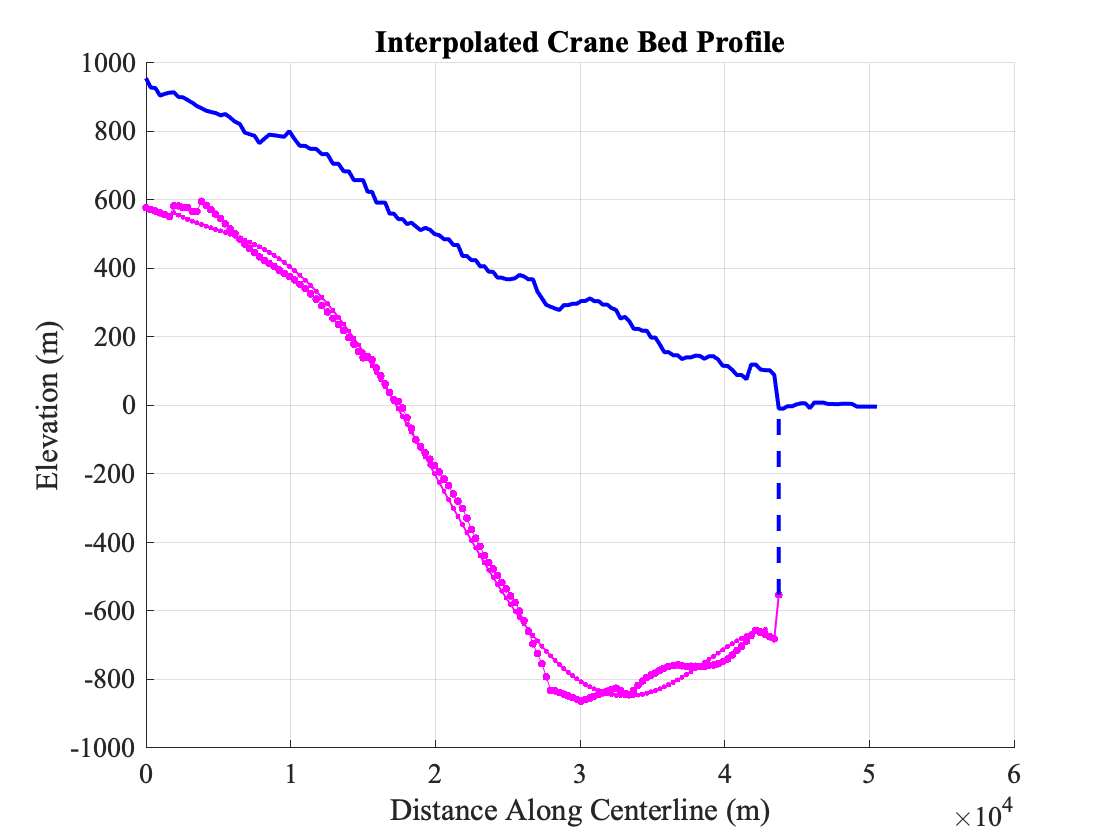

hb_poly(136:138) = hb(136:138);

% Plot results
figure; hold on; grid on;
plot(x(1:fl_end),hb,'.-m','markersize',10);
plot(x,h_cl,'-b','LineWidth',2);
plot(x(1:fl_end),hb_poly,'.-m','linewidth',1);
plot(icecliff(:,1),icecliff(:,2),'--b','LineWidth',2);
title('Interpolated Crane Bed Profile');
set(gca,'FontName','Times New Roman','FontSize',14);
xlabel('Distance Along Centerline (m)');
ylabel('Elevation (m)');
hold off;


% Save variables
cd /Users/raineyaberle/Desktop/Research/BedandSurface
save('Crane_CalculatedBed.mat','hb');
save('Crane_CalculatedBed_poly.mat','hb_poly');
disp('Variables saved');

Variables saved
